# Planetary Accretion – Toy Model

This is a simplified gravitational *n*-body model of planetary accretion by planetesimal collisions including compositional evolution of planetary embryos. 

Planetesimals are initialised with randomised masses and positions to populate a disk of around 20 AU radius. A gas giant initially orbiting at 5 AU distance from the central star and its effect on orbital dynamics are included in the model.

The model tracks three compositional components: metal, rock, and ice. It assumes a distribution of more metal- to more rock-dominated in the inner disk, and ice-dominated outside the snow-line at 5 AU radius.

Collisions are detected if bodies move within an effective collision radius. The total mass, composition, and momentum of two collided bodies are fully merged into a new body positioned at their mutual centre of mass and moving at a velocity that conserves their momentum.

clear; close all; clc;  % clear workspace

## Set Model Parameters

Set run identifier tag. Output figures will be saved to folder `deform/out/runID`. Set new identifier for every model run.

runID = 'demo';  % change RunID for every parameter test

Set seed for random number generator. Adjust the slider to your favourite number to produce uniquely randomised results.

rng(10);  % change the random seed

Set interval of time steps between plotting and saving figures. Select lower interval for testing, higher for full model run.

nop  =  50;  % select lower interval for testing, higher interval for full run

Set model stopping time in years. Select shorter stopping time for testing, higher for full run. Note that model will stop automatically if grid distortion around faults exceeds a threshold.

tend  =  1000;  % select shorter stopping time for testing, higher for full run

Set initial condition for *n-*body simulation. Select the number of planetesimals, their mean mass, the mass of the gas giant planted at 5 AU, and the mass of the central star. All masses are given in Earth Masses.

N     = 1000;   % initial number of bodies; try 100, 200, 500, 1000
MPls  = 0.01;  % mean planetesimal mass [Earth Masses]; try 0.005, 0.01, 0.02
MGgt  = 100;   % mass of gas giant [Earth Masses]; try 1, 10, 100, 1000
MStr  = 1e4;   % mass of central star [Earth Masses]; leave as is.

Set effective collision radius: the radial distance to which nearby bodies are merged as collisions.

cls   = 0.05;     % collision radius [relative]; try 0.025, 0.05, 0.075

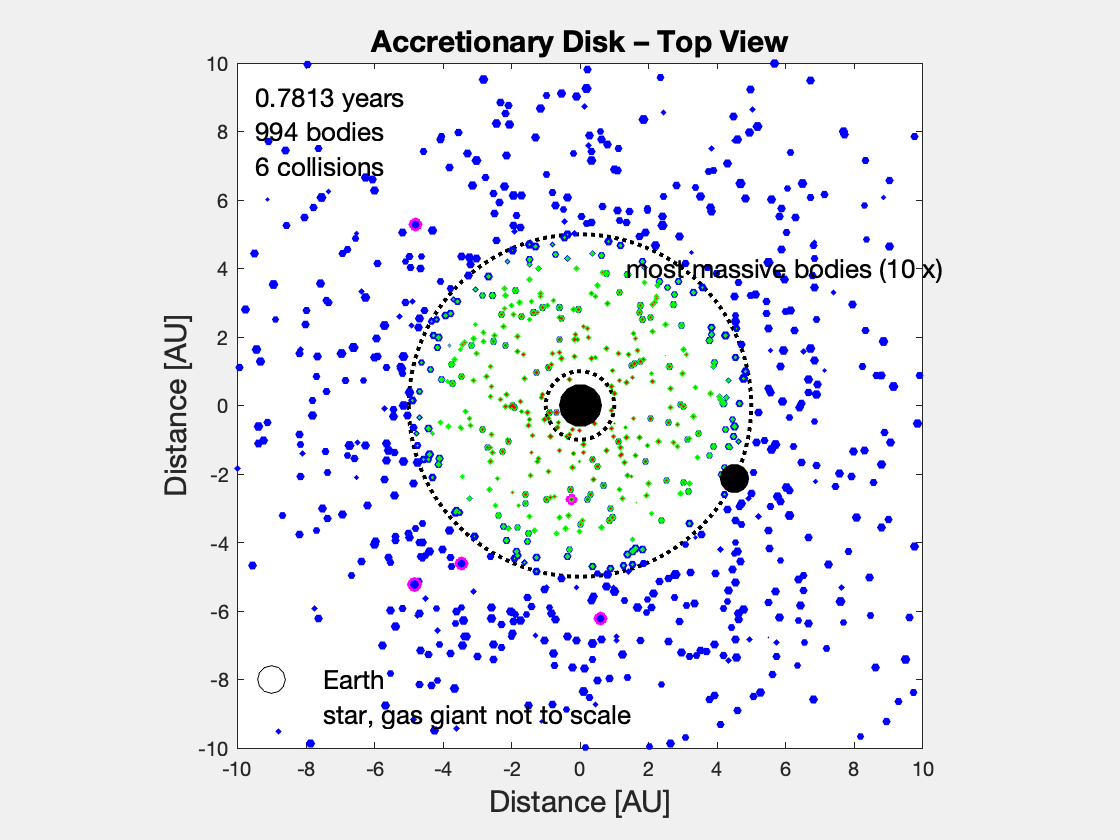

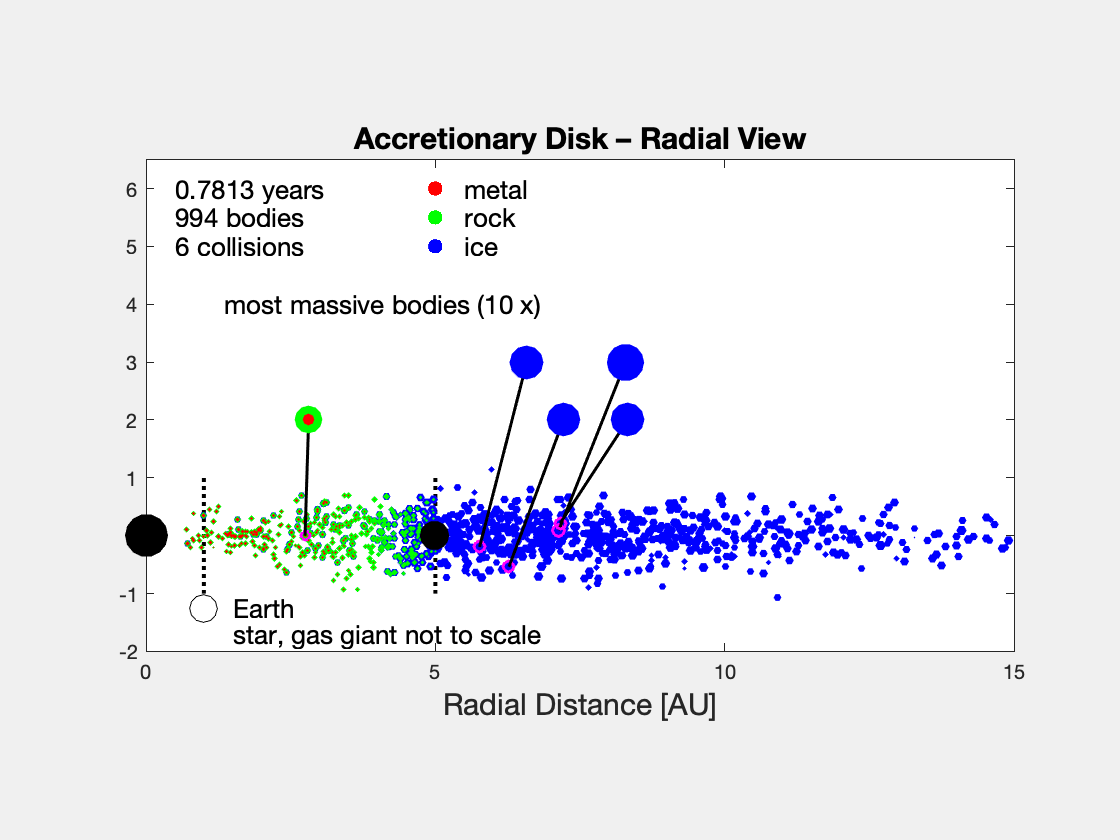

% create output directory
if ~exist(['./op/',runID],'dir'); mkdir(['./op/',runID]); end

% initialise body mass and position
M  = [MStr; MGgt; max(MPls/100,normrnd(MPls,MPls/3,N-2,1))];
X  = [0,0,0; 5,0,0; randn(N-2,3).*[5,5,0.25]];

% initialise body composition (rock = 1; ice = 0)
r  = sum((X-X(1,:)).^2,2).^0.5 + 1e-32;
C  = [min(1,max(0,0.5-r./8)),zeros(N,1),min(1,max(0,r-4))];
C(:,2) = 1-sum(C,2);

% calculate radii
Rtot = sum(M.*C(:,1:3)./[2,1,0.5]+1e-16,2).^(1/3);
Rrck = sum(M.*C(:,1:2)./[2,1    ]+1e-16,2).^(1/3);
Rmtl = sum(M.*C(:,1:1)./[2      ]+1e-16,2).^(1/3);

% calculate initial orbital velocity
R  = (X-X(1,:))./r;
V  = sqrt(M(1)./r) .* [R(:,2),-R(:,1),R(:,3)] .* (1+randn(N,3).*[0;0.01;ones(N-2,1).*0.05]);

% calculate duration of 1 year (orbital period for body of M = 1, R = 1)
yr = 2*pi/sqrt(M(1));

% calculate time step size
dt = yr/64;

CLS  = 0;  % initialise collision count
time = 0;  % initialise time
k    = 1;  % initialise time step counter

% main time stepping loop
while time < tend*yr
    
    % update time and step count
    time = time + dt;
    k    = k + 1;
    
    % store previous position
    Xo = X;
    
    % calculate new orbital velocity
    for nj = 1:N
        D  = sum((X-X(nj,:)).^2,2).^0.5 + 1e-16;
        Fj = - (M.*M(nj))./D.^2 .* (X-X(nj,:))./D;
        V  = V + Fj./M .* dt;
    end
    V = V - V(1,:);
    
    X  = Xo + V.*dt;  % update position of all bodies
    
    % detect collisions
    nj = 1;
    while nj < N
        Do      = sum((Xo-Xo(nj,:)).^2,2).^0.5 + 1e-16;
        D       = sum((X -X (nj,:)).^2,2).^0.5 + 1e-16;
        ind     = (D+Do)./2 < cls;
        ind(nj) = 0;
        ind     = find(ind>0);
        
        % merge collided bodies
        for i = 1:length(ind)
            Mc        = M(ind(i));
            Vc        = V(ind(i),:);
            X(nj,:)   = ((M(ind(i)).*X(ind(i),:)) + M(nj).*X(nj,:))./(M(ind(i))+M(nj));
            V(nj,:)   = ((M(ind(i)).*V(ind(i),:)) + M(nj).*V(nj,:))./(M(ind(i))+M(nj));
            C(nj,:)   = ((M(ind(i)).*C(ind(i),:)) + M(nj).*C(nj,:))./(M(ind(i))+M(nj));
            M(nj)     = M(ind(i))+ M(nj);
            N         = N-1;
        end
        
        % remove consumed bodies
        X(ind,:)  = [];
        Xo(ind,:) = [];
        V(ind,:)  = [];
        C(ind,:)  = [];
        M(ind)    = [];
        Rtot(ind) = [];
        
        CLS = CLS + length(ind); % update collision counter
        nj  = nj+1; % move to check collisions for next body
    end
    
    % update radii
    Rtot = sum(M.*C(:,1:3)./[2,1,0.5]+1e-16,2).^(1/3);
    Rrck = sum(M.*C(:,1:2)./[2,1    ]+1e-16,2).^(1/3);
    Rmtl = sum(M.*C(:,1:1)./[2      ]+1e-16,2).^(1/3);
    
    
    % plot and print model progress
    scl = 250;
    if ~mod(k-1,nop)
        figure(1); clf; set(gcf,'Visible','on','PaperSize',[20,15]);
        rectangle('Position',[-1 -1  2  2],'Curvature',[1,1],'EdgeColor','k','LineStyle',':','LineWidth',2); hold on; box on; axis equal;
        rectangle('Position',[-5 -5 10 10],'Curvature',[1,1],'EdgeColor','k','LineStyle',':','LineWidth',2);
        scatter(X(3:N,1),X(3:N,2),Rtot(3:N).^2.*scl,[0,0,1],'filled');
        scatter(X(3:N,1),X(3:N,2),Rrck(3:N).^2.*scl,[0,1,0],'filled');
        scatter(X(3:N,1),X(3:N,2),Rmtl(3:N).^2.*scl,[1,0,0],'filled');
        scatter(X(1:2,1),X(1:2,2),M(1:2).^(2/12).*1e2,zeros(2,3),'filled');
        
        [~,I] = sort(M,'descend');
        [~,J] = sort(r(I(3:7)));
        for n = 1:5
            ind = I(J(n)+2);
            scatter(X(ind,1),X(ind,2),(Rtot(ind)+0.01).^2.*scl,[1,0,1],'LineWidth',1.5)
        end
        text(1.35,4,'most massive bodies (10 x)','FontSize',13);
        
        scatter(-9,-8,(1/1.5).^(2/3).*scl,[0,0,0]);
        text(-7.5,-8,'Earth','FontSize',13);
        text(-7.5,-9,'star, gas giant not to scale','FontSize',13);
        
        text(0.025,0.95,[num2str(time/yr,4),' years'],'Units','normalized','FontSize',13);
        text(0.025,0.90,[int2str(N  ),' bodies'    ],'Units','normalized','FontSize',13);
        text(0.025,0.85,[int2str(CLS),' collisions'],'Units','normalized','FontSize',13);
        
        axis([X(1,1)-10,X(1,1)+10,X(1,2)-10,X(1,2)+10]);
        title('Accretionary Disk – Top View','FontSize',15);
        xlabel('Distance [AU]','FontSize',15)
        ylabel('Distance [AU]','FontSize',15)
        
        print(gcf,['./op/',runID,'/',runID,'_top_',int2str((k-1)/nop)],'-dpdf','-painters','-fillpage');
        drawnow;
        
        figure(2); clf; set(gcf,'Visible','on','PaperSize',[20,15]);
        r = sum((X-X(1,:)).^2,2).^0.5 + 1e-32;  % update radial distance to sun
        line([1,1],[-1,1],'Color','k','LineStyle',':','LineWidth',2); hold on; box on; axis equal;
        line([5,5],[-1,1],'Color','k','LineStyle',':','LineWidth',2); hold on; box on; axis equal;
        scatter(r(3:N),X(3:N,3),Rtot(3:N).^2.*scl,[0,0,1],'filled'); hold on; box on; axis equal;
        scatter(r(3:N),X(3:N,3),Rrck(3:N).^2.*scl,[0,1,0],'filled');
        scatter(r(3:N),X(3:N,3),Rmtl(3:N).^2.*scl,[1,0,0],'filled');
        scatter(r(1:2),X(1:2,3),M(1:2).^(2/12).*1e2,zeros(2,3),'filled');
        
        [~,I] = sort(M,'descend');
        [~,J] = sort(r(I(3:7)));
        for n = 1:5
            ind = I(J(n)+2);
            scatter(r(ind),X(ind,3),(Rtot(ind)+0.01).^2.*scl,[1,0,1],'LineWidth',1.5)
            a  = 0.25; r0 = 2.5;
            ra = min(11,max(0.25,r(ind).*(1+a)-r0*a));
            line([r(ind),ra],[X(ind,3),3-mod(n,2)],'Color','k','LineWidth',1.5);
            scatter(ra,3-mod(n,2),sum(M(ind).*C(ind,1:3).*[0.5,1,2]+1e-16).^(2/3).*scl*10,[0,0,1],'filled'); hold on; box on; axis equal;
            scatter(ra,3-mod(n,2),sum(M(ind).*C(ind,1:2).*[0.5,1  ]+1e-16).^(2/3).*scl*10,[0,1,0],'filled');
            scatter(ra,3-mod(n,2),sum(M(ind).*C(ind,1:1).*[0.5    ]+1e-16).^(2/3).*scl*10,[1,0,0],'filled');
        end
        text(1.35,4,'most massive bodies (10 x)','FontSize',13);
        
        scatter(1.0,-1.25,(1/1.5).^(2/3).*scl,[0,0,0]);
        text(1.5,-1.25,'Earth','FontSize',13);
        text(1.5,-1.70,'star, gas giant not to scale','FontSize',13);
        
        text(0.5,6.0,[num2str(time/yr,4),' years'],'FontSize',13);
        text(0.5,5.5,[int2str(N  ),' bodies'      ],'FontSize',13);
        text(0.5,5.0,[int2str(CLS),' collisions'  ],'FontSize',13);
        
        plot(5,6.0,'r.','MarkerSize',20);
        plot(5,5.5,'g.','MarkerSize',20);
        plot(5,5.0,'b.','MarkerSize',20);
        
        text(5.5,6.0,'metal','FontSize',13);
        text(5.5,5.5,'rock' ,'FontSize',13);
        text(5.5,5.0,'ice'  ,'FontSize',13);
        
        axis([0,X(1,1)+15,X(1,3)-2,X(1,3)+6.5]);
        title('Accretionary Disk – Radial View','FontSize',15);
        xlabel('Radial Distance [AU]','FontSize',15)
        
        print(gcf,['./op/',runID,'/',runID,'_rad_',int2str((k-1)/nop)],'-dpdf','-painters','-fillpage');
        drawnow;
        
    end
    
end